% Fisher, Hirth Flow Law
% First write a script to solve for solubility 
% Solubility (C (P,T))
% C(P,T) = Asol(P)exp[-Hsol(P/RT)]
% Hsol(P) = 28000 + 4500ln(P/200*10^6)
% Asol(P) = .0037exp[Hsol(P)/R*453K]

% Input Variables
P = 500e6; % Pa (e6 converts to Pa)
T = 623.15; % K
R = 8.314; % (J/mol*K)

%Solve for Solubility C(P,T)
Hsol = 28000 + 4500*(log(P/200e6)) % J/mol

Hsol = 3.2123e+04

Asol = .0037* exp(Hsol/(R*453)) 

Asol = 18.7248

CPT = Asol* exp((-Hsol/(R*T)))

CPT = 0.0380



% Flow Law
%   eps = (AC*sig/d^3)^(-Q/RT)
% eps = strain rate (s^-1)
A = 1.5e-6; 
C = CPT

C = 0.0380

Sig = 70;
Sig1 = 20; % differential stress (MPa)
Sig2 = 30; % differential stress (MPa)
Sig3 = 40; % differential stress (MPa)
Sig4 = 50; % differential stress (MPa)
Sig5 = 60; % differential stress (MPa)
Q = 50000; %(J/mol)
d = 10

d = 10

%Grain size (Sample um)
%d = linspace(0.1,50,50); % Grain size (Range um)
% Input differential stress, grain size
% Returns strain rate for each differential stress
eps = (A*C*Sig/(d^3))* exp(-Q/(R*T))

eps = 2.5674e-13

eps1 = (A*C*Sig1./(d.^3))* exp(-Q./(R*T));
eps2 = (A*C*Sig2./(d.^3))* exp(-Q./(R*T));
eps3 = (A*C*Sig3./(d.^3))* exp(-Q./(R*T));
eps4 = (A*C*Sig4./(d.^3))* exp(-Q./(R*T));
eps5 = (A*C*Sig5./(d.^3))* exp(-Q./(R*T));

% Input volume strain, single or range of values - Isolate at 95%
VolStrain_70 = 0.7;
VolStrain_80 = 0.8;
VolStrain_85 = 0.85;
VolStrain_90 = 0.9;
VolStrain_95 = 0.95;
VolStrain_98 = 0.98;

% Solve for time given strain rate, volume strain

%Strain Time (Sample)
t_samp = VolStrain_98/eps

t_samp = 3.8171e+12


% Strain Time: 70%
t1_70 = VolStrain_70./eps1; %Seconds
%t2_70 = VolStrain_70./eps2; 
%t3_70 = VolStrain_70./eps3; 
%t4_70 = VolStrain_70./eps4; 
t5_70 = VolStrain_70./eps5; 

% Strain Time: 80%
t1_80 = VolStrain_80./eps1; %Seconds
%t2_80 = VolStrain_80./eps2; 
%t3_80 = VolStrain_80./eps3; 
%t4_80 = VolStrain_80./eps4; 
t5_80 = VolStrain_80./eps5; 

% Strain Time: 85%
t1_90 = VolStrain_90./eps1; %Seconds
%t2_90 = VolStrain_90./eps2; 
%t3_90 = VolStrain_90./eps3; 
%t4_90 = VolStrain_90./eps4; 
t5_90 = VolStrain_90./eps5; 

% Strain Time: 98%
t1_98 = VolStrain_98./eps1; %Seconds
%t2_98 = VolStrain_98./eps2; 
%t3_98 = VolStrain_98./eps3; 
%t4_98 = VolStrain_98./eps4; 
t5_98 = VolStrain_98./eps5; 

% Convert time (s) to Myr
s2yr= 3.1536e13;

% Time (Sample)
Myr = t_samp/s2yr

Myr = 0.1210


% Time: 70% Loss
Myr1_70 = t1_70./s2yr; % Millions of years
Myr2_70 = t2_70./s2yr;
Myr3_70 = t3_70./s2yr; 
Myr4_70 = t4_70./s2yr; 
Myr5_70 = t5_70./s2yr; 

% Time: 80% Loss 
Myr1_80 = t1_80./s2yr; % Millions of years
%Myr2_80 = t2_80./s2yr 
%Myr3_80 = t3_80./s2yr 
%Myr4_80 = t4_80./s2yr 
Myr5_80 = t5_80./s2yr; 

% Time: 90% Loss
Myr1_90 = t1_90./s2yr; % Millions of years
%Myr2_90 = t2_90./s2yr 
%Myr3_90 = t3_90./s2yr 
%Myr4_90 = t4_90./s2yr 
Myr5_90 = t5_90./s2yr;

% Time: 95% Loss 
Myr1_98 = t1_98./s2yr; % Millions of years
%Myr2_98 = t2_98./s2yr 
%Myr3_98 = t3_98./s2yr 
%Myr4_98 = t4_98./s2yr 
Myr5_98 = t5_98./s2yr; 

% Figure (grain size vs time of def by differential stress) 

% Plot: 70%
M70_20 = plot(Myr1_70, d, 'Linewidth', 1.5, 'Color', '#FF2400')

M70_20 =   Line with properties:

              Color: [1 0.1412 0]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0.3026
              YData: 10

  Show all properties


hold on;
%plot(Myr2_70, d, 'Linewidth', 1.5, 'Color', '#FF2400')
%plot(Myr3_70, d, 'Linewidth', 1.5, 'Color', '#FF2400')
%plot(Myr4_70, d, 'Linewidth', 1.5, 'Color', '#FF2400')
M70_60 = plot(Myr5_70, d, 'Linewidth', 1.5, 'Color', '#FF2400')

M70_60 =   Line with properties:

              Color: [1 0.1412 0]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0.1009
              YData: 10

  Show all properties



%Plot: 80%
M80_20 = plot(Myr1_80, d, 'Linewidth', 1.5, 'Color', '#FFEA00')

M80_20 =   Line with properties:

              Color: [1 0.9176 0]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0.3458
              YData: 10

  Show all properties


%plot(Myr2_80, d, 'Linewidth', 1.5, 'Color', '#FFEA00')
%plot(Myr3_80, d, 'Linewidth', 1.5, 'Color', '#FFEA00')
%plot(Myr4_80, d, 'Linewidth', 1.5, 'Color', '#FFEA00')
M80_60 = plot(Myr5_80, d, 'Linewidth', 1.5, 'Color', '#FFEA00')

M80_60 =   Line with properties:

              Color: [1 0.9176 0]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0.1153
              YData: 10

  Show all properties



%Plot: 85%
M90_20 = plot(Myr1_90, d, 'Linewidth', 1.5, 'Color', '#48AAAD')

M90_20 =   Line with properties:

              Color: [0.2824 0.6667 0.6784]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0.3891
              YData: 10

  Show all properties


%plot(Myr2_90, d, 'Linewidth', 1.5, 'Color', '#48AAAD')
%plot(Myr3_90, d, 'Linewidth', 1.5, 'Color', '#48AAAD')
%plot(Myr4_90, d, 'Linewidth', 1.5, 'Color', '#48AAAD')
M90_60 = plot(Myr5_90, d, 'Linewidth', 1.5, 'Color', '#48AAAD')

M90_60 =   Line with properties:

              Color: [0.2824 0.6667 0.6784]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0.1297
              YData: 10

  Show all properties



%Plot: 95%
M98_20 = plot(Myr1_98, d, 'Linewidth', 1.5, 'Color', '#311465')

M98_20 =   Line with properties:

              Color: [0.1922 0.0784 0.3961]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0.4236
              YData: 10

  Show all properties


%plot(Myr2_98, d, 'Linewidth', 1.5, 'Color', '#311465')
%plot(Myr3_98, d, 'Linewidth', 1.5, 'Color', '#311465')
%plot(Myr4_98, d, 'Linewidth', 1.5, 'Color', '#311465')
M98_60 = plot(Myr5_98, d, 'Linewidth', 1.5, 'Color', '#311465')

M98_60 =   Line with properties:

              Color: [0.1922 0.0784 0.3961]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 0.1412
              YData: 10

  Show all properties


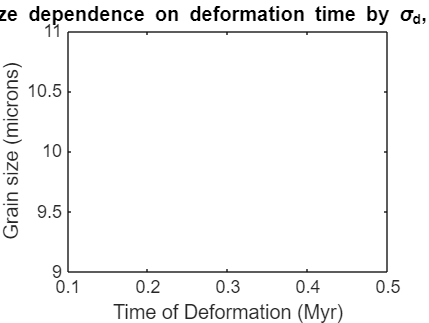


%set(gca,'Yscale','log');
%set(gca,'Xscale','log');
xlabel('Time of Deformation (Myr)')
ylabel('Grain size (microns)')
title('Grain size dependence on deformation time by \sigma_d, mass loss')
hold off;

% FLOW LAW EQ ON GRAPH 







% Figure 2: (Grain size vs time of def by mass loss)
% Start by making mass loss set values for lines 
% Using Chen et al. mass loss ranges we'll go from aroud 70% mass loss to
% 98% mass loss in a few intervals 